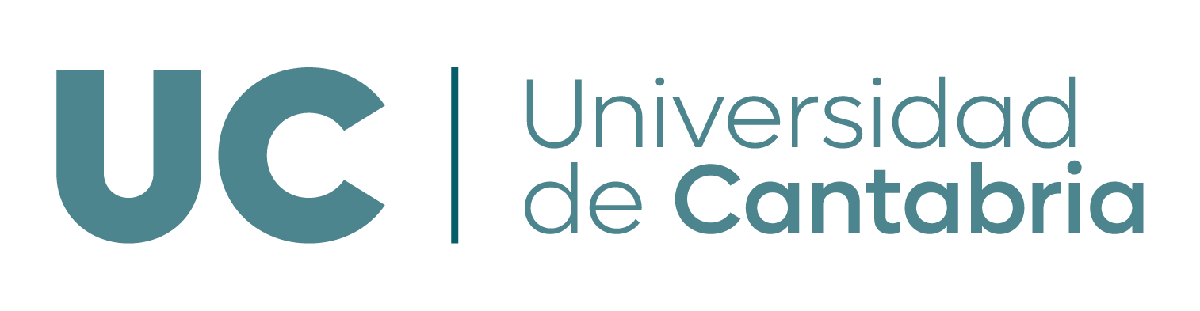

***Grado en Ingeniería en Tecnologías Industriales***

**G414: Álgebra y Geometría**

# ** Dependencia lineal y cambio de base**

*Sara Pérez Carabaza (sara.perezcarabaza@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es). *

**Objetivos**

- Determinar si un conjunto de vectores es libre o ligado

- Determinar relaciones de dependencia entre vectores 

- Obtener una base de un subespacio

- Matriz de cambio de base

**Funciones de MATLAB utilizadas en este guion: **`rank, null, rref`

format rat
clear all;

## **1. Dependencia e independencia lineal**

En este apartado veremos cómo determinar si un conjunto de vectores es un conjunto linealmente independiente (libre) o linealmente dependiente (ligado). Además veremos dos métodos para hallar relaciones de dependencia entre los vectores en caso de que se trate de un conjunto linealmente dependiente.

### **Método 1****: matriz escalonada **

Sea el conjunto de vectores $$S=\lbrace (5,-9,6,4), (-3,4,-2,-1), (0,-7,8,7), (2,0,4,1)\rbrace$$de $\mathbb{R}^4$. Sabemos que el conjunto $S$ será libre (o linealmente independiente) si la única manera de expresar el vector  nulo como combinación lineal de los vectores de $S$ es que todos los coeficientes de la combinación lineal sean nulos. Esto equivale a comprobar que el sistema homogéneo que tiene por matriz de coeficientes $A$ los vectores de $S$, colocados por columnas, tenga tan sólo la solución trivial.

Es decir, para nuestro ejemplo analizamos el tipo del siguiente sistema de ecuaciones homogéneo:


$$
\alpha_1
\left(\begin{array}{c}
     5\\  
     -9\\  
     6\\  
     4\end{array}\right)
+\alpha_2\left(\begin{array}{c}
     -3\\  
     4\\  
     -2\\  
     -1\end{array}\right)
+\alpha_3 \left(\begin{array}{c}
     0\\  
     -7\\  
     8\\  
     7\end{array}\right)
+\alpha_4\left(\begin{array}{c}
     2\\  
     0\\  
     4\\  
     1\end{array}\right)=
\left(\begin{array}{cccc}
     5 & -3 & 0 & 2\\  
     -9 & 4 & -7 & 0\\  
     6 & -2 & 8 & 4\\  
     4 & -1 & 7 & 1\end{array}\right)
\left(\begin{array}{cccc}
     \alpha_1 \\  
   \alpha_2 \\  
     \alpha_3\\  
     \alpha_4\end{array}\right)
=\left(\begin{array}{cccc}
    0 \\  
   0 \\  
     0\\  
     0\end{array}\right)$$


Por tanto, para estudiar la dependencia de un conjunto de vectores estudiamos el tipo de solución de un sistema lineal homogéneo. Los sistemas homogéneos siempre son compatibles, luego únicamente es necesario estudiar si el sistema es SCI (vectores ligados) o SCD (vectores libres). Luego bastará con comprobar si el rango de la matriz de vectores por columnas coincide con el número de columnas. 

% defino los vectores del conjunto
u1 = [5 -9 6 4]';
u2 = [-3 4 -2 -1]';
u3 = [0 -7 8 7]';
u4 = [2 0 4 1]';

% clasifico el sistema homogéneo de interés
A = [u1 u2 u3 u4]  % matriz de coefs. 
rank(A)  % R-F: S.C.I. -> el conjunto S es ligado

El comando *rank *nos indica cuál es el número de vectores independientes. En este caso tenemos 4 vectores y rango 3, luego el conjunto de 4 vectores es ligado, por lo que sabemos que al menos un vector puede expresarse como combinación lineal del resto de vectores. El rango de 3 nos indica que el mayor subconjunto libre de vectores de S que podemos escoger es de 3 vectores. Pueden existir varios grupos de 3 vectores libres. Una manera fácil de encontrar un grupo de 3 vectores libres es a través de la escalonada reducida de la matriz que forman los vectores al colocarlos por columnas, los vectores de las columnas pivotales formarán un conjunto libre. 

rref(A)  % identifico u1, u2 y u4 como l.i. (columnas pivotales)

Las columnas pivotales son la 1, 2 y 4. Luego los vectores $$S=\lbrace (5,-9,6,4), (-3,4,-2,-1),  (2,0,4,1)\rbrace$$forman un conjunto libre y por tanto deberán tener rango 3. Vamos a comprobarlo:

rank(A(:,[1 2 4]))%subconjunto de 3 vectores l.i. (u1, u2 y u4)

Además de permitirnos identificar rápidamente un subconjunto de vectores libres, la matriz escalonada equivalente también nos da información de las** relaciones de dependencia de los vectores de un conjunto**. Al tratarse $S$ de un conjunto ligado, esto nos asegura que algunos de los vectores pueden expresarse como C.L. del resto. Específicamente, la matriz escalonada reducida nos permite identificar fácilmente como expresar las columas no pivotales como C.L de los vectores de las columnas pivotales. En este ejemplo la única columna no pivotal (la tercera) es el vector [3 5 0 0], podemos observar fácilmente en la matriz escalonada reducida como este vector se obtiene como: multiplicando la primera columna por 3 y sumando la segunda columna multiplicada por 5. Comprobémoslo:

% podemos expresar el vector u3 como combinación lineal del resto:
u3
3*u1+5*u2

***Nota******:*** *Siempre colocaremos los vectores de cualquier conjunto del que queramos estudiar su dependencia/independencia lineal en columnas. Esto es importante ya que al escalonar la matriz las relaciones  entre los vectores columnas se mantienen (pero esto no es así para los vectores fila).*

### **Método 2: resolución sistema lineal homogéneo**

Otro método para hallar las relaciones de dependencia de un conjunto de vectores es resolviendo el sistema lineal homogéneo $A\vec{x}=\vec{0}$, donde $A$ es la matriz con los vectores del conjunto en columas. 


$$
\alpha_1
\left(\begin{array}{c}
     5\\  
     -9\\  
     6\\  
     4\end{array}\right)
+\alpha_2\left(\begin{array}{c}
     -3\\  
     4\\  
     -2\\  
     -1\end{array}\right)
+\alpha_3 \left(\begin{array}{c}
     0\\  
     -7\\  
     8\\  
     7\end{array}\right)
+\alpha_4\left(\begin{array}{c}
     2\\  
     0\\  
     4\\  
     1\end{array}\right)=
\left(\begin{array}{cccc}
     5 & -3 & 0 & 2\\  
     -9 & 4 & -7 & 0\\  
     6 & -2 & 8 & 4\\  
     4 & -1 & 7 & 1\end{array}\right)
\left(\begin{array}{cccc}
     \alpha_1 \\  
   \alpha_2 \\  
     \alpha_3\\  
     \alpha_4\end{array}\right)
=\left(\begin{array}{cccc}
    0 \\  
   0 \\  
     0\\  
     0\end{array}\right)$$


Para resolver sistema lineales homogéneos el comándo `null` nos será muy útil. Como ya hemos visto, si el sistema es SCD (y por tanto el conjunto de vectores fuera libre) entonces solo tendrá la solución trivial y `null` nos devolvería un vector vacío. Para SCI como este ejemplo, la función `null` nos dará un vector por cada parámetro libre.

rank(A)%SCI, 1 parámetro libre
null(A, 'rational') % relación de dependencia: -3*u1-5*u2+1*u3+0*u4 = 0

La solución del sistema lineal homogéneo son las combinaciones lineales de los vectores devueltos por la función `null`. En este ejemplo:


$$\left(\begin{array}{cccc}
     \alpha_1 \\  
   \alpha_2 \\  
     \alpha_3\\  
     \alpha_4\end{array}\right)=
\lambda \left(\begin{array}{cccc}
    -3 \\  
   -5 \\  
    1\\  
     0\end{array}\right)$$


El SCI tiene infinitas soluciones, dando el valor $\lambda=1
$ obtenemos una de ellas:


$$
-3
\left(\begin{array}{c}
     5\\  
     -9\\  
     6\\  
     4\end{array}\right)
-5\left(\begin{array}{c}
     -3\\  
     4\\  
     -2\\  
     -1\end{array}\right)
+1 \left(\begin{array}{c}
     0\\  
     -7\\  
     8\\  
     7\end{array}\right)
+0\left(\begin{array}{c}
     2\\  
     0\\  
     4\\  
     1\end{array}\right)
=\left(\begin{array}{cccc}
    0 \\  
   0 \\  
     0\\  
     0\end{array}\right)$$


Es decir $-3\vec{u_1} -5\vec{u_2} +1\vec{u_3} +0\vec{u_4}=\vec{0}$. Claramente vemos que podemos expresar unos vectores como C.L. de otros del conjunto, por lo que el conjunto es ligado. Por ejemplo, podemos expresar el tercer vector como C.L de los dos primeros $\vec{u_3} =3\vec{u_1} +5\vec{u_2} $

## **2.Coordenadas y cambio de base**

### 2.1 Coordenadas

Como sabemos, podemos expresar cualquier vector de un subespacio vectorial $S$ como combinación lineal de los vectores de un sistema generador de $S$. Si además el sistema generador es base, esta combinación lineal es única, y sus coeficientes reciben el nombre de coordenadas. 

**Ejemplo 1**. Queremos hallar las coordenadas del vector  $\vec{v}=\left(\begin{array}{c}
     7\\  
     8\\  
     9\end{array}\right)$ en la base $B=\{ \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right), \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right),
 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right) \}$.

Para empezar definimos la matriz B que tiene como columnas los vectores de la base B.

%matriz cuyas columnas son los vectores de la base B
B=[ 1 1 0; 1 2 0 ; 1 1 4]'

Para hallar las coordenadas del vector $\vec{v}$ en la base B necesitamos resolver el siguiente sistema:


$$\left(\begin{array}{c}
     7\\  
     8\\  
     9\end{array}\right)_{BC}=
\alpha_1 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+\alpha_2 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+\alpha_3 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)=\left(\begin{array}{ccc}
     1 & 1 & 1\\  
     1 & 2 & 1\\  
     0 & 0 & 4\end{array}\right)\left(\begin{array}{c}
     \alpha_1\\  
     \alpha_2\\  
     \alpha_3\end{array}\right)_{B}

\quad \rightarrow 
\left(\begin{array}{ccc}
     1 & 1 & 1\\  
     1 & 2 & 1\\  
     0 & 0 & 4\end{array}\right)\left(\begin{array}{c}
     \alpha_1\\  
     \alpha_2\\  
     \alpha_3\end{array}\right)_{B}=\left(\begin{array}{c}
     7\\  
     8\\  
     9\end{array}\right)_{BC}
$$


v=[7 8 9]';%coordenadas vector en la base canonica
vB=B\v%coordenadas del vector en la base B

Es decir, $\left(\begin{array}{c}
     7\\  
     8\\  
     9\end{array}\right)_{BC}=
\frac{15}{4}\left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+1 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+\frac{9}{4}\left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)$. Las coordenadas del vector $\vec{v}=\left(\begin{array}{c}
     7\\  
     8\\  
     9\end{array}\right)$  en la base B son $(\frac{15}{4},1,\frac{9}{4})$

Resumiendo, tenemos que:


$$
7 \left(\begin{array}{c}
     1\\  
     0\\  
     0\end{array}\right)+8\left(\begin{array}{c}
     0\\  
     1\\  
     0\end{array}\right)+9
 \left(\begin{array}{c}
     0\\  
     0\\  
     1\end{array}\right)=
15/4 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+ 1 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+ 9/4 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)$$


**Ejemplo 1 (continuación)**. Siguiendo con la base $B=\{ \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right), \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right),
 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right) \}$, queremos hallar las coordenadas del vector $\vec{v}=\left(\begin{array}{c}
    1\\  
   2\\  
     3\end{array}\right)_{B}$ en la base canónica de $\mathbb{R}^3$. $ $

Es decir tenemos el vector $\vec{v}=\left(\begin{array}{c}
    1\\  
   2\\  
     3\end{array}\right)_{B}$. Donde 1, 2 y 3 son las coordenadas del vector en la base B. Luego:


$$\left(\begin{array}{c}
     1\\  
    2\\  
     3\end{array}\right)_{B}=
1 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+2 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+3
 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)$$


Ahora estamos buscando las coordenadas del vector $\vec{v}$ en la base canónica:


$$1 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+2 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+3
 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)=\alpha_1 \left(\begin{array}{c}
     1\\  
     0\\  
     0\end{array}\right)+\alpha_2 \left(\begin{array}{c}
     0\\  
     1\\  
     0\end{array}\right)+\alpha_3
 \left(\begin{array}{c}
     0\\  
     0\\  
     1\end{array}\right)
\leftrightarrow 
\left(\begin{array}{ccc}
     1 & 1 & 1\\  
     1 & 2 & 1\\  
     0 & 0 & 4\end{array}\right)\left(\begin{array}{c}
     1\\  
     2\\  
     3\end{array}\right)=\left(\begin{array}{ccc}
     1 & 0 & 0\\  
     0 & 1 & 0\\  
     0 & 0 & 1\end{array}\right)\left(\begin{array}{c}
     \alpha_1\\  
      \alpha_2\\ 
     \alpha_3\end{array}\right)$$


simplemente necesitamos hacer un producto matricial para hallarlas

wB=[1 2 3]';%coordenadas del vector w en la base B
%hallamos coordenadas del vector en la base BC
wBc=B*wB(1)

Ya tenemos la solución:$\vec{w}=
\left(\begin{array}{c}
     6\\  
     8\\  
     12\end{array}\right)_{BC}$. 

Recapitulando, podemos comprobar que:


$$
1 \left(\begin{array}{c}
     1\\  
     1\\  
     0\end{array}\right)+2 \left(\begin{array}{c}
     1\\  
     2\\  
     0\end{array}\right)+3
 \left(\begin{array}{c}
     1\\  
     1\\  
     4\end{array}\right)=6 \left(\begin{array}{c}
     1\\  
     0\\  
     0\end{array}\right)+8\left(\begin{array}{c}
     0\\  
     1\\  
     0\end{array}\right)+12
 \left(\begin{array}{c}
     0\\  
     0\\  
     1\end{array}\right)
\Leftrightarrow
\left(\begin{array}{ccc}
     1 & 1 & 1\\  
     1 & 2 & 1\\  
     0 & 0 & 4\end{array}\right)\left(\begin{array}{c}
     1\\  
     2\\  
     3\end{array}\right)=\left(\begin{array}{ccc}
     1 & 0 & 0\\  
     0 & 1 & 0\\  
     0 & 0 & 1\end{array}\right)\left(\begin{array}{c}
  6\\  
8\\ 
  12\end{array}\right)$$


### 2.2 Matriz cambio de base

Un espacio vectorial tiene infinitas bases posibles, todas con el mismo número de vectores (dimensión del subespacio). Un vector tendrá unas coordenadas diferentes dependiendo de la base. La matriz de cambio de base $M_{B_1 \rightarrow B_2}$nos permite obtener las coordenadas de un vector en la base $B_2
$ a partir de las coordenadas del vector en la base $B_1
$. 

**Ejemplo (diapositivas clase)**. Se consideran las siguientes dos bases de $\mathbb{R}^2$.

%vectores base B1
v1=[1 0]'; v2=[1 3]';
%vectores base B2
u1=[0 1]'; u2=[1 1]';

 La matriz $M_{B_1 \rightarrow B_2}$ tiene como columnas las coordenadas de los vectores de la base $B_1
$ expresados en la base $B_2
$. Necesitamos por tanto resolver los siguientes dos sistemas:

 

%hallamos coordenadas del vector v1=(1,0) de B1 en la base B2
A=[u1 u2];
coord1=A\v1;
%hallamos coordenadas del vector v2=(1,3) de B1 en la base B2  
A=[u1 u2];
coord2=A\v2
%matriz de cambio de base de B1->B2
MB1B2=[coord1 coord2]

Esta matriz  $M_{B_1 \rightarrow B_2}$ nos permite obtener múy facilmente las coordenadas en la base $B_2
$ de cualquier vector expresado en la base $B_1
$. 

Por ejemplo, dado $\vec{w}=
\left(\begin{array}{c}
2  \\
     1\end{array}\right)_{B_1}$ haciendo el producto $M_{B_1 \rightarrow B_2}{(\vec{w})}_{B_1}$ obtenemos que sus coordenadas en la base $B_2
$ son $\vec{w}=
\left(\begin{array}{c}
0  \\
    3\end{array}\right)_{B_2}$

wB1=[2,1]'; %coordenadas del vector w en la base B1
wB2=MB1B2*wB1 %obtenemos coordenadas del vector w en la base B2

Para obtener la matriz de cambio de base  $M_{B_2 \rightarrow B_1}$ , podemos seguir un procedimiento análogo al anterior. O simplemente utilizar que $M_{B_2 \rightarrow B_1}$ es la inversa de $M_{B_1 \rightarrow B_2}$.

MB2B1=inv(MB1B2)

Por ejemplo, siguiendo con el ejemplo anterior podemos comprobar  que  $\vec{w}=
\left(\begin{array}{c}
0  \\
    3\end{array}\right)_{B_2}$ corresponde a $\vec{w}=
\left(\begin{array}{c}
2  \\
     1\end{array}\right)_{B_1}$:

MB2B1*wB2 %coincide con wB1

**Ejercicio.** Resuelve el ejemplo  del apartado anterior (2.1 Coordenadas) utilizando las matrices de cambio de base.

## Bibliografía 

- Guiones para Matlab realizados por Rodrigo García Manzanas y Ruth Carballo Fidalgo para la asignatura de Álgebra y Geometría del Grado en Ingeniería Civil.